clear
clc

## GRID CREATION

y1_by_x1 = 0.4;
x1 = 10;
nx = 200;
ny = round(y1_by_x1*nx)

ny = 80

y1 = (ny/nx)*x1

y1 = 4


[X, Y] = MESH_GRID(0, 0, x1, y1, nx+1, ny+1);

%Time Step Calculation
dt = (X(1,2) - X(1,1))/100;
dx = (X(1,2) - X(1,1));
dy = (Y(2,1) - Y(1,1));

### POINT EMITTER LOCATION & POTENTIAL

xe = 1;
ye = y1/2;
Anode_pos = [xe,ye];
%Potential
Volt =  2;

### COLLECTOR CREATION

% Generate coordinates
NACA_digits = '0012'; % Example NACA 2412 airfoil
num_points = 200 % Number of points to generate

num_points = 200

[x, y] = CURVEGEN_Airfoil(NACA_digits, num_points,-10);
x = x+1;
y = y+y1/2;
collector = [x,y];

% Temporary CIRCLE
collector = CURVEGEN_Circle(xe+1+1,y1/2,1,200);


## Plot

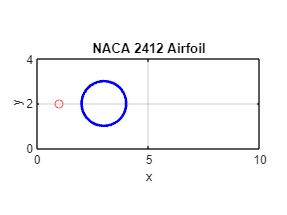

figure;
plot(collector(:,1), collector(:,2), 'b', 'LineWidth', 2);
hold on
plot(Anode_pos(1),Anode_pos(2),'or');
axis equal;
xlabel('x');
ylabel('y');
title('NACA 2412 Airfoil');
xlim([0 x1])
ylim([0 y1])
grid on;
hold off

### **BOUNDARY CONDITIONS (CFD)**

INTERIOR = [];

%INLET VELOCITIES
% [Boundary,VELOCITIES,P_NORMALS] = BC_Vel_in_Free(0.1,X,Y,"left",0);

%WALL Boundaries
[Boundary,VELOCITIES,P_NORMALS] = BC_End_Wall(X,Y,"down",0);
[Boundary,VELOCITIES,P_NORMALS] = BC_End_Wall(X,Y,"up",1,Boundary,VELOCITIES,P_NORMALS);
[Boundary,VELOCITIES,P_NORMALS,INTERIOR] = BC_Custom_Obstacle(collector, X, Y,1,Boundary,VELOCITIES,P_NORMALS);

## PLOTTING (Don't Run to Save time)

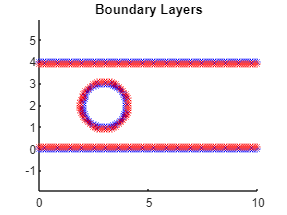

figure

hold on
for i = 1:length(Boundary(:,1))
    if VELOCITIES(i,1)==0 && VELOCITIES(i,2)==0
        plot((Boundary(i,2)-1)*dx,(Boundary(i,1)-1)*dy,'b*');
    end
end

for i = 1:length(Boundary(:,1))
    if VELOCITIES(i,1)==0 && VELOCITIES(i,2)==0
        plot(P_NORMALS(i,1),P_NORMALS(i,2),'r*');
    end
end

axis equal
title("Boundary Layers")

hold off

## FORCING FUNCTION (ELECTRO-STATIC)

[Ex1,Ey1,V,rho] = E_GRID(X,Y,collector,Anode_pos,Volt);
% RRRRRRRRRRRRRRRRRECHECK

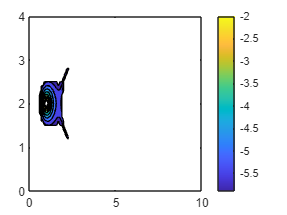

Ex = Ex1;
Ey = Ey1;
Ex(isnan(Ex)) = 0;
Ey(isnan(Ey)) = 0;

k = 1;
Ex = k*(Ex).*rho;
Ey = k*(Ey).*rho;
E_MAG = sqrt(Ex.*Ex + Ey.*Ey);

Ex = (Ex)/(max(max(E_MAG)));
Ey = (Ey)/(max(max(E_MAG)));

for i=1:height(INTERIOR)
            Ex(INTERIOR(i,1),INTERIOR(i,2)) = 0;
            Ex(INTERIOR(i,1),INTERIOR(i,2)) = 0;
            Ey(INTERIOR(i,1),INTERIOR(i,2)) = 0;
            Ey(INTERIOR(i,1),INTERIOR(i,2)) = 0;
end

Ex(abs(E_MAG)<0.1*rms(rms(E_MAG))) = 0;
Ey(abs(E_MAG)<0.1*rms(rms(E_MAG))) = 0;
% 
Ex(abs(E_MAG)>100*rms(rms(E_MAG))) = 0;
Ey(abs(E_MAG)>100*rms(rms(E_MAG))) = 0;
E_MAG = sqrt(Ex.*Ex + Ey.*Ey);

contourf(X,Y,log((abs(E_MAG))),'LineStyle','-','LineWidth',0.1)
colorbar


E_MAG = sqrt(Ex.*Ex + Ey.*Ey);


## PLOTTING ELECTRO-STATIC FIELDS (Don't Run to Save time)

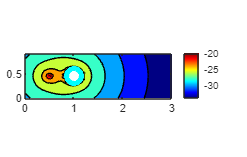

[X_plot, Y_plot] = MESH_GRID(0, 0, x1, y1, 60, 60);
[E_x,E_y,V_plot,rho1] = E_GRID(X_plot,Y_plot,collector,Anode_pos,Volt);
E_x = (E_x)/(max(max(E_x))-min(min(E_x)));
E_y = (E_y)/(max(max(E_y))-min(min(E_y)));

k = 1e-8;
E_MAG = sqrt(E_x.*E_x + E_y.*E_y);
E_x = k*(E_x).*rho1;
E_y = k*(E_y).*rho1;

[~,~,~,INTERIOR1] = BC_Custom_Obstacle(collector, X_plot, Y_plot,0);

for i=1:height(INTERIOR1)
            E_x(INTERIOR1(i,1),INTERIOR1(i,2)) = 0;
            E_x(INTERIOR1(i,1),INTERIOR1(i,2)) = 0;
            E_y(INTERIOR1(i,1),INTERIOR1(i,2)) = 0;
            E_y(INTERIOR1(i,1),INTERIOR1(i,2)) = 0;
end
E_MAG1 = sqrt(E_x.*E_x + E_y.*E_y);


contourf(X_plot,Y_plot,log((abs(E_MAG1))),'LineStyle','-','LineWidth',0.1)
colormap("jet")
% shading interp
hold on
plot([collector(:,1);collector(1,1)],[collector(:,2);collector(1,2)],'cyan','LineWidth',4)
plot(Anode_pos(1),Anode_pos(2),'r*','MarkerSize',4,'MarkerFaceColor','r')
colorbar
cutoff = -inf;
axis equal
hold off

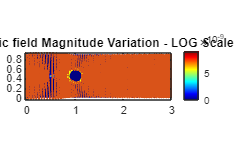


E_MAG = sqrt(E_x.*E_x + E_y.*E_y);

contourf(X_plot,Y_plot,(E_MAG),400,'LineStyle','none','LineWidth',0.1)
axis equal
title("Electric field Magnitude Variation - LOG Scale")
colorbar

hold on
plot(collector(:,1), collector(:,2), 'y', 'LineWidth', 2);
quiver(X_plot(V_plot>cutoff),Y_plot(V_plot>cutoff),(E_x(V_plot>cutoff))./E_MAG(V_plot>cutoff),(E_y(V_plot>cutoff))./E_MAG(V_plot>cutoff),'LineWidth',1);

axis equal
hold off

## FLOW INITIALIZATION

% INITIALIZE U,V,P & B Variables
u = X*0;
v = X*0;
p = X*0;
b = p;

% Boundary conditions (PRESSURE ONLY)    
for i=1:height(P_NORMALS)

    p1 = finterp(p, X, Y, [P_NORMALS(i,1), P_NORMALS(i,2)]);
    p(Boundary(i,1),Boundary(i,2)) = p1;

end

% Boundary conditions (VELOCITY ONLY)

for i=1:height(P_NORMALS)
    u(Boundary(i,1),Boundary(i,2)) = VELOCITIES(i,1);
    v(Boundary(i,1),Boundary(i,2)) = VELOCITIES(i,2);
end

for i=1:height(INTERIOR)
    u(INTERIOR(i,1),INTERIOR(i,2)) = 0;
    v(INTERIOR(i,1),INTERIOR(i,2)) = 0;
end


t_end = 5;
nt = t_end/dt

nt = 5000

## FLOW ITERATION

nt = 5000;
k_factor = 1;

for i = 1:nt

    if rem(i,round(nt/20))==0
        i
    end
    
    if ismember(1,isnan(u))
        disp("NAAAAA")
        return
    end

    u1=u;
    v1 = v;
    p1 = p;
    
    [u, v, p] = CFD_INC(u, v, X, Y, p, b, dt, 40, Boundary, VELOCITIES, P_NORMALS, INTERIOR, k_factor*Ex, k_factor*Ey);

end

i = 250

i = 500

i = 750

i = 1000

i = 1250

i = 1500

i = 1750

i = 2000

i = 2250

i = 2500

i = 2750

i = 3000

i = 3250

i = 3500

i = 3750

i = 4000

i = 4250

i = 4500

i = 4750

i = 5000

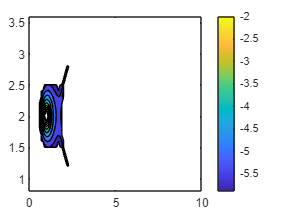

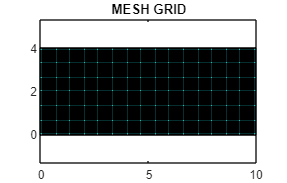

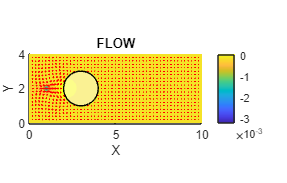

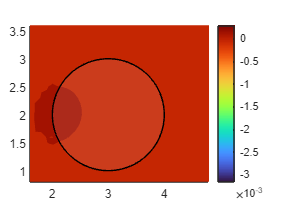

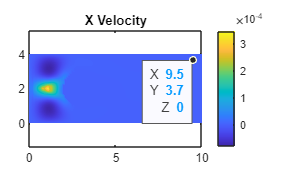

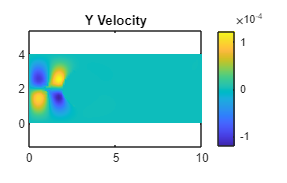


PLOT_CFD(X,Y,p,u,v,collector, Anode_pos)